Př. 6: Při kontrole životnosti 50 výrobků bylo z dat zjištěno, že střední doba do poruchy výrobku je 27400 hodin a směrodatná odchylka 5400 hodin (popsáno normálním rozdělením). Určete na hladině významnosti 5 %, zda lze přijmout fakt výrobce, že střední doba do poruchy je rovna 30 000 hodin.

H_0: u = 30 000h

H_A u != 30 000h

n = 50

n = 50

X = 27400

X = 27400

E = 30000

E = 30000

mi = 5400

mi = 5400

alpha = 0.05

alpha = 0.0500


T = (X - E) * sqrt(n) / mi

T = -3.4046

Lowerbound = tinv(alpha / 2, n - 1)

Lowerbound = -2.0096

Upperbound = tinv(1 - alpha / 2, n - 1)

Upperbound = 2.0096


% nebo

p_value = 2 * tcdf(-3.4, n - 1)

p_value = 0.0013

**Na hladině významnosti 5% zamítáme hypotézu H0, že střední hiodnota do poruchy je 30 000 hodin.**

Př. 7: Mějme následující data, kde první řádek představuje hodnotu parametru před tepelnou úpravou (vzorek 1, řádek 1) a v druhém řádku jsou uvedeny výsledky na stejných kusech po tepelné úpravě (vzorek 2, řádek 2). Data jsou z normálního rozdělení. Zjistěte na hladině významnosti 5 %, zda:   

- Je shodná hodnota parametru u obou výběrů		(H0: u1 = u2, H1: u1 != u2)

- došlo ke zvýšení parametru po tepelné úpravě. 	(H0: u1 >= u2, H1: u1 < u2)

x=[35.0,36.0,36.3,36.8,37.2,37.6,38.3,39.1,39.3,39.6,39.8;
     37.2,38.1,38.2,37.9,37.6,38.3,39.2,39.4,39.7,39.9,39.9];

% Jsou shodné
[h0, p_shod, ~, ~] = ttest(diff, 0, alpha, "both")

h0 = 1

p_shod = 0.0024


% H0: u2 - u1 >= 0
% Zvýšení parametru

diff = x(2, :) - x(1, :)

diff =     2.2000    2.1000    1.9000    1.1000    0.4000    0.7000    0.9000    0.3000    0.4000    0.3000    0.1000


alpha = 0.05

alpha = 0.0500

[h1, p_zvys, ~, ~] = ttest(diff, 0, alpha, "right")

h1 = 1

p_zvys = 0.0012

**Na hladině významnosti 5% zamítáme hypotézu H0, že je shodná hodnota parametru u obou výběrů, protože p-value je menší než hladina významnosti (0.05 > 0.0024).**

**Na hladině významnosti 5% zamítáme hypotézu H0, že došlo ke zvýšení parametru po tepelné úpravě, protože p-value je menší než hladina významnosti (0.05 > 0.0012)**

Př. 8: Mějme data: x=[-6,-3,-1,0,2,3,5,6,7,8,9,11,12,14,15,18,22,28,32,37,41]. Otestujte na hladině významnosti 5 % znaménkovým testem, zda medián je roven 25.

Pozn: Nepředpokládáme, že data jsou z normálního rozdělení.

H0: m = 25

HA: m != 25

alpha = 0.05

alpha = 0.0500

m = 25

m = 25

x = [-6,-3,-1,0,2,3,5,6,7,8,9,11,12,14,15,18,22,28,32,37,41];
[p, h] = signtest(x, m)

p = 0.0072

h = logical
   1


**Na hladině významnosti 5% zamátáme hypotézu H0, že je medián roven 25, protože p-value je menší než hladina významnosti.**

Př. 16: Balicí zařízení je seřízeno na začátku ranní směny a následně kontrolováno u odpolední směny. Byly zjištěny následující hodnoty hmotnosti výrobků:

Ráno=[98.5, 98.6, 98.7, 98.7, 98.7, 98.8, 98.9, 99.2, 99.3, 99.3] g

Odpoledne=[98.1,98.2, 98.3, 98.4, 98.6, 98.7, 98.8, 98.9, 99.0, 99.0] g

Otestujte na hladině významnosti 5 %, zda je shodné seřízení stroje, tj. zda rozptyl hmotnosti výrobku je shodný.  

H0: sx1 = sx2, HA: sx1 != sx2

alpha = 0.05

alpha = 0.0500

x_1 = [98.5, 98.6, 98.7, 98.7, 98.7, 98.8, 98.9, 99.2, 99.3, 99.3]

x_1 =    98.5000   98.6000   98.7000   98.7000   98.7000   98.8000   98.9000   99.2000   99.3000   99.3000


x_2 = [98.1,98.2, 98.3, 98.4, 98.6, 98.7, 98.8, 98.9, 99.0, 99.0]

x_2 =    98.1000   98.2000   98.3000   98.4000   98.6000   98.7000   98.8000   98.9000   99.0000   99.0000


[h, p] = vartest2(x_1, x_2)

h = 0

p = 0.7187

**Na hladině 5% přijímáme hypotézu H0, že je seřízení strojů shodné, protože p-value je vyšší než hladina významnosti.**

Př. 19: Jak by dopadl výsledek testování vlivu tepelné úpravy z párového testu (př. 7), jestliže bychom neznali informaci, že testování proběhlo na stejných kusech. Data jsou z normálního rozdělení. Zjistěte na hladině význanosti 5 %, zda je shodná hodnota parametru (H0: u1=u2, H1: u1 != u2).

x=[35.0,36.0,36.3,36.8,37.2,37.6,38.3,39.1,39.3,39.6,39.8;

     37.2,38.1,38.2,37.9,37.6,38.3,39.2,39.4,39.7,39.9,39.9];

x=[35.0,36.0,36.3,36.8,37.2,37.6,38.3,39.1,39.3,39.6,39.8;
    37.2,38.1,38.2,37.9,37.6,38.3,39.2,39.4,39.7,39.9,39.9];
alpha = 0.05;

[h, p] = ttest2(x(1, :), x(2, :), alpha, "both", "equal")

h = 0

p = 0.1120

**Na hladině 5% nezamítáme hypotézu H0, že je hodnota parmetru shodná, protože p-value je větší než hladina významnosti.**

*Jestli hypotézu nezamítáme, nebo přijímáme, záleží na tom, jestli jsou měření provedena na stejných kusech??? Něco takovýho Pepik říkal.*

Př. 23: Mějme naměřená data ve vektorech x a y. Otestujte na hladině významnosti 5 %, zda median je shodný. Testu obvykle předchází testování shody rozptylů. Předpokládáme, že typ rozdělení je shodný (testování se naučíme v kapitole 9). 

H0: mx = my, HA: mx != my

x=[12,14,16,18,19,19,21,23,25,27,31,35,39,42]

x =     12    14    16    18    19    19    21    23    25    27    31    35    39    42


y=[15,18,21,24,27,29,32,35]

y =     15    18    21    24    27    29    32    35


[p, h] = ranksum(x, y, 0.05)

p = 0.7070

h = logical
   0


**Na hladině 5% přijímáme hypotézu H0, protože p-value je větší než hladina významnosti.**

**Př. 24: **Bylo zjišťováno, zda ve městě a na vesnici je při odpovědi na určitou otázku shoda v relativní četnosti. Ve městě bylo dotázáno 1240 respondentů a odpovědělo ano 325. Na vesnici bylo dotázáno 741 respondentů a odpovědělo ano 287. Otestujte na hladině významnosti 5 % shodu názoru ve městě a na vesnici.

h0: město = vesnice

ha: město != vesnice

p_mesto = 325 / 1240;
p_ves = 287 / 741;

T = (p_mesto - p_ves) / sqrt(((p_mesto * (1 - p_mesto) / 1240)) + (p_ves * (1 - p_ves) / 741))

T = -5.7380

pvalue = 2 * min(normcdf(T, 0, 1))

pvalue = 9.5775e-09

**Na hladině 5% zamítáme hypotézu H0, že se relativní četnost ve městě a na vesnici shodují.**

**Př. 25: **Výrobní stroj se seřídí začátkem směny. Kontrola výrobků probíhá vždy po jedné hodině a chceme zjistit, zda nedochází k většímu rozptylu určitého rozměru. Otestujte na hladině významnosti 5 %, zda rozptyly dat jsou shodné. Použijte Bartlettův i Leveneův test.

H0: G^2_1 = G^2_2 G^2_3 = G^2_4

HA: Alespoň jedna skupina nemá shodný G^2 

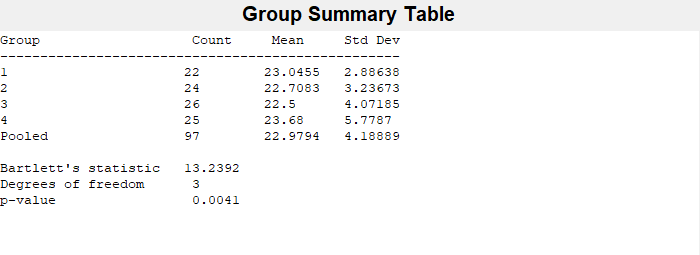

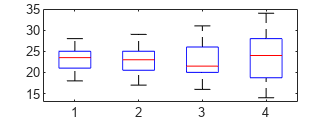

p_barlett = 0.0041

x1=[18,19,19,19,20,21,21,22,22,23,23,24,24,24,25,25,25,26,26,26,27,28];
x2=[17,18,18,19,19,20,21,21,22,22,22,23,23,23,23,24,24,25,25,26,26,27,28,29] ;
x3=[16,17,18,18,18,19,20,20,20,20,21,21,21,22,23,23,23,24,25,26,27,27,28,28,29,31];
x4=[14,15,16,16,17,18,19,20,22,22,22,23,24,25,25,27,27,27,28,28,28,31,31,33,34];

skupina1(1:length(x1)) = 1;
skupina2(1:length(x2)) = 2;
skupina3(1:length(x3)) = 3;
skupina4(1:length(x4)) = 4;

data = [x1, x2, x3, x4]';
skupina = [skupina1, skupina2, skupina3, skupina4]';
[p_barlett] = vartestn(data, skupina, "on", "classical")

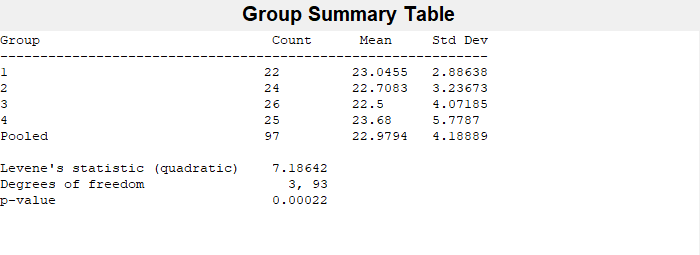

p_leven = 2.1630e-04

[p_leven] = vartestn(data, skupina, "on", "robust")

**Na hladině významnosti 5% zamítáme hypotézu H0, že jsou ropztyly shodně.**

**Př. 26: **Na datech z příkladu 25 otestujte, zda na hladině významnosti 5 % jsou střední hodnoty shodné. Použijte jednofaktorovou ANOVA metodu.

H0: G_1 = G_2 G_3 = G_4

HA: Alespoň jedna skupina nemá shodný G 

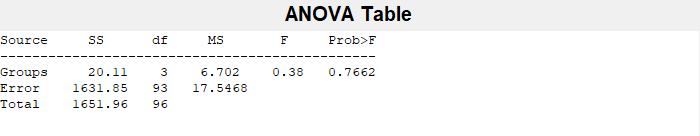

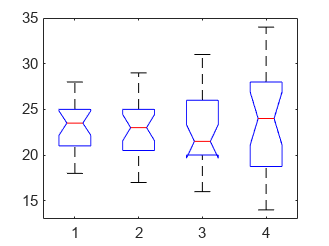

p = 0.7662

x1=[18,19,19,19,20,21,21,22,22,23,23,24,24,24,25,25,25,26,26,26,27,28];
x2=[17,18,18,19,19,20,21,21,22,22,22,23,23,23,23,24,24,25,25,26,26,27,28,29] ;
x3=[16,17,18,18,18,19,20,20,20,20,21,21,21,22,23,23,23,24,25,26,27,27,28,28,29,31];
x4=[14,15,16,16,17,18,19,20,22,22,22,23,24,25,25,27,27,27,28,28,28,31,31,33,34];

skupina1(1:length(x1)) = 1;
skupina2(1:length(x2)) = 2;
skupina3(1:length(x3)) = 3;
skupina4(1:length(x4)) = 4;

data = [x1, x2, x3, x4]';
skupina = [skupina1, skupina2, skupina3, skupina4]';
[p,anovatab, stats] = anova1(data, skupina, "on");

**Na hladině významnosti 5% přijímáme hypotézu H0, že střední hodnoty skupin jsou shodné.**

**Př. 28:** Mějme naměřená data z 5 skupin (každá o 100 prvcích), která jsou uložena v souboru P0828.mat. Ověřte předpoklady a zjistěte, zda střední hodnota je u všech výběrů shodná. Pokud ne, porovnejte skupiny mezi sebou. 

(co lze očekávat: data pravděpodobně z normálního rozdělení, shodné rozptyly, rozdílné střední hodnoty)

data = load("P0828.mat").x

data =    12.3527
   16.1977
   20.3122
   17.2327
   17.1986
   15.2111
   15.4143
   15.5877
    4.8041
   17.5731


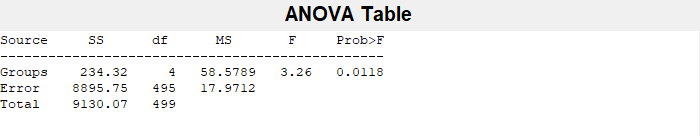

skupiny = [1 2 3 4 5]' * ones(1,100);
skupiny = reshape(skupiny.', 1, [])';

[p_anova,anovatab, stats_anova] = anova1(data, skupiny, "on");

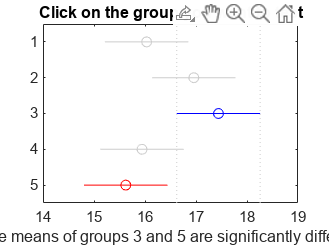

comparision =     1.0000    2.0000   -2.5603   -0.9250    0.7104    0.5344
    1.0000    3.0000   -3.0442   -1.4088    0.2265    0.1294
    1.0000    4.0000   -1.5449    0.0904    1.7258    0.9999
    1.0000    5.0000   -1.2261    0.4092    2.0446    0.9603
    2.0000    3.0000   -2.1192   -0.4838    1.1515    0.9286
    2.0000    4.0000   -0.6199    1.0154    2.6508    0.4378
    2.0000    5.0000   -0.3012    1.3342    2.9695    0.1702
    3.0000    4.0000   -0.1361    1.4993    3.1346    0.0904
    3.0000    5.0000    0.1827    1.8180    3.4534    0.0205
    4.0000    5.0000   -1.3166    0.3188    1.9541    0.9841


means =    16.0318    0.4239
   16.9568    0.4239
   17.4406    0.4239
   15.9413    0.4239
   15.6226    0.4239


[comparision, means] = multcompare(stats_anova, "Alpha",0.05)